# Relatório de Atividade 06 - Modelos de predição não-paramétricos

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Estimação e Identificação de Sistemas 21.2*

*14 de setembro de 2021*

Esse documento tem por objetivo descrever a caracterização de um preditor para um sistema a partir de técnicas não paramétricas.

## Introdução

Nos exercícios anteriores, a identificação de uma planta era realizada conforme um modelo de referência. No entanto, as técnicas diretas de estimação restringem o sistema a uma família de modelos. Existem métodos que contornam essa problemática, as quais são nomeadas não paramétricas.

Nesse estudo, serão descritas duas formas de analisar a função de transferência $G(q)$ de uma planta desconhecida: primeiramente no domínio do tempo; e, em segundo lugar, no domínio da frequência.

### Análise no domínio do tempo

Se um sistema é generalizado pela formulação


$$y(t)=G_0(t)u(t)+v(t) = \sum_{k=1}^{\infty}g_0(k)u(t-k)+v(t)$$


para $u(t)$ o sinal pulso com magnitude $\alpha$ e $v(t)$um ruído, a saída é dada por


$$y(t)=\alpha g_0(t)+v(t)$$


para $g_0(t)$ a resposta ao impulso da função de transferência $G_0(q)$. Se o ruído for desprezível, é possível determinar os coeficientes da resposta ao impulso por;


$$g_0(t)=\frac{y(t)}{\alpha}$$


Todavia, muitos processos não são estáveis para sinais de pulso como entrada. Além disso, para $u(t)$ de magnitude $\alpha$, há um erro $v(t)/\alpha$ na estimativa acima.

Uma alternativa seria adotar $u(t)$ como um degrau de magnitude $\alpha$ a partir do instante $t=0$. Dessa forma, a saída do sistema é dada por:


$$y(t)=\alpha\sum^t_{k=1}g_0(k)+v(t)$$


Sendo assim, as estimativas de $g_0(t)$ são então encontradas por:


$$g_0(t)=\frac{y(t)-y(t-1)}{\alpha}$$


com um erro de $[v(t)-v(t-1)]/\alpha$. Apesar desse erro ser inferior ao computado pelo modelo que adota o pulso como sinal de entrada, não é possível garantir que os parâmetros estimados são próximos dos coeficientes reais da planta. 

Uma forma de evitar que a estimativa derive da formulação de $y(t)$(que possuí uma parcela $v(t)$) é realizar a análise a partir da correlação dos sinais $u(t)$ e $y(t)$, a qual é:


$$R_{yu}(\tau)=\sum_{k=1}^{\infty}g_0(k)R_u(k-\tau)$$


Essa expressão foi discutida durante a Atividade 02, e, por isso, seu desenvolvimento não será aqui explicitado. Se $u(t)$ for escolhido como um ruído branco, tem-se que:


$$R_u(\tau) = \begin{cases}\alpha, \tau = 0\\ 0, \tau \neq 0\end{cases}$$


Logo, substuindo na equação de $R_{yu}(\tau)$:


$$g_0(\tau) = \frac{R_{yu}(\tau)}{\alpha}$$


Se $u(t)$ não for um ruído branco, é possível truncar $R_{u}(\tau)$ e encontrar uma aproximação de $G_0(q)$. Outra alternativa é empregar um filtro de "pré-branqueamento" em ambos sinais de saída $y(t)$ e entrada $u(t)$ para transformar $u(t)$ em um sinal o mais aproximado possível de um ruído branco antes de calcular as covariâncias. 

### Análise no domínio da frequência

Outro método para determinar o modelo de um processo desconhecido é a análise em frequência. Suponha $u(t)=\alpha\cos{(\omega t)}$, para $t=0,1,2,...$, logo:

$y(t) = \alpha|G_0(e^{j\omega})|\cos{(\omega t+\varphi)}+v(t)$, para $\varphi=\angle G_0(e^{j\omega})$

Dessa forma, $y(t)$ é um sinal cosseinoidal adicionado a um ruído. Conforme descrito por [1], a estimativa $\hat{G}_N(q)$ pode ser encontrada considerando os seguintes passos:

- Calcule os seguintes somatórios para $N$ amostras:


$$I_c(N) = \frac{1}{N}\sum_{t=1}^Ny(t)\cos{\omega t} = \frac{\alpha}{2}|G_0(e^{j\omega})|\cos{\varphi}+\frac{\alpha}{2N}|G_0(e^{j\omega})|\sum_{t=1}^N\cos{(2\omega t+\varphi)}+\frac{1}{N}\sum_{t=1}^Nv(t)\cos{\omega t}$$



$$I_s(N) = \frac{1}{N}\sum_{t=1}^Ny(t)\sin{\omega t} = -\frac{\alpha}{2}|G_0(e^{j\omega})|\sin{\varphi}+\frac{\alpha}{2N}|G_0(e^{j\omega})|\sum_{t=1}^N\sin{(2\omega t+\varphi)}+\frac{1}{N}\sum_{t=1}^Nv(t)\sin{\omega t}$$


- Estime $\hat{G}_N$ tal que $|\hat{G}_N(e^{j\omega})|=\frac{\sqrt{I_c^2(N)+I_s^2(N)}}{\alpha/2}$ e$\angle \hat{G}_N(e^{j\omega}) = \arctan{\frac{I_s(N)}{I_c(N)}}$.

Ao repetir o processo para uma série de frequências $\omega$, pode-se obter a estimativa $\hat{G}_N(e^{j\omega})$ para múltiplas frequências. Entretanto, muitos sistemas não admitem entradas senoidais devido à persistência desse sinal. Sendo assim, de forma generalizada, pode-se estimar, de forma grosseira, que:


$$\hat\hat{G}_N(e^{j\omega})=\frac{Y_N(\omega)}{U_N(\omega)}$$


para $\omega$ a frequência do sinal de entrada, $Y_N(\omega)$ a DFT da saída $y(t)$ e $U_N(\omega)$ a TDF (transformada discreta de Fourier) da entrada $u(t)$. A função $\hat\hat{G}_N(e^{j\omega})$ é nomeada estimada empírica da função de transferência (*empirical transfer-function estimate* - ETFE), e só existe para $U_N(\omega)\neq 0$. 

Conforme descrito no Teorema 2.1 de [1]:


$$Y_N(\omega)=G_0(e^{j\omega})U_N(\omega)+V_N(\omega)+R_N(\omega)$$


para $R_N(\omega)$ o resíduo do truncamento da entrada $u(t)$ no somatório e $V_N(\omega)$ a DFT do ruído $v(t)$. Dessa forma, substituindo $Y_N(\omega)$ na expressão de $\hat\hat{G}_N(e^{j\omega})$:


$$\hat\hat{G}_N(e^{j\omega})=G_0(e^{j\omega})+\frac{R_N(\omega)+V_N(\omega)}{U_N(\omega)}$$


Logo, o valor esperado da estimativa $\hat\hat{G}_N(e^{j\omega})$ é:


$$E\hat\hat{G}_N(e^{j\omega})=G_0(e^{j\omega})+\frac{R_N(\omega)}{U_N(\omega)}+\frac{EV_N(\omega)}{U_N(\omega)}$$


Como $EV_N = 0$, é evidente que a equivalência entre o valor verdadeiro $G_0(z)$ e a ETFE depende unicamente da parcela $R_N(\omega)/U_N(\omega)$. Existem estratégias para minimizar esse erro de viés (BIAS) conforme a excitação do sistema, isto é, aplicando sinais de entrada $u(t)$ que minimizem a respectiva fração $R_N(\omega)/U_N(\omega)$.

Conforme discutido no Capítulo 2 de [1], o espectro $\Phi_v(\omega)$ é uma versão suavizada da curva $|V_N(\omega)|^2$. Dessa forma, pode-se descrever que:

$E|V_N(\omega)|^2=\Phi_v(\omega)+\rho(N)$, para $\rho<C/N$

para $|u(t)|\leq C$, para todo $t$. Sendo assim, a variância da ETFE não decai com o aumento de $N$, mas é proporcional à relação sinal ruído na respectiva frequência. Como o ruído $v(t)$ é gaussiano, isto é, cada amostra independe do valor nos instantes anteriores e posteriores, é evidente que as propriedades em frequências diferentes são descorrelacionadas.

Uma solução para esse problema seria aumentar não a quantidade, mas a qualidade dos dados (*features*) de entrada do estimador, ou seja, assumir que as frequências são associadas entre si conforme a seguinte média ponderada:

$\hat{G}_N(e^{j\omega_0})=\frac{\sum_{k=k_1}^{k_2}\alpha_k\hat\hat{G}_N(e^{2\pi jk/N})}{\sum_{k=k_1}^{k_2}\alpha_k}$ , para $\alpha_k=\frac{|U_N(2\pi k/N)|^2}{\Phi_v(2\pi k/N)}$

sendo $\omega_0$ a frequência em que quero estimar $G(z)$, e assumindo que $G_0(e^{j\omega})$ é constante no intervalo $2\pi k_1/N < \omega < 2\pi k_2/N$. É evidente que $\alpha_k$ é o inverso da relação sinal-ruído para a frequência $2\pi k/N$. 

Para $N$ grande, é possível aproximar o somatório por uma integral de tal forma que:

$\hat{G}_N(e^{j\omega_0})=\frac{\int_{\omega-\Delta\omega}^{\omega+\Delta\omega}W_\gamma(\xi-\omega_0)\alpha(\xi)\hat\hat{G}_N(e^{j\xi})d\xi}{\int_{\omega-\Delta\omega}^{\omega+\Delta\omega}W_\gamma(\xi-\omega_0)\alpha(\xi)d\xi}$, para $W_\gamma(\xi)$ um degrau unitário centrado em $\xi=0$ e largura $2\Delta\omega$,

Substituindo $\alpha(\xi) = {|U_N(\xi)|^2}/{\Phi_v(\omega_0)}$, obtém-se que:


$$\hat{G}_N(e^{j\omega_0})=\frac{\int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)|U_N(\xi)|^2\hat\hat{G}_N(e^{j\xi})d\xi}{\int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)|U_N(\xi)|^2d\xi}$$


Entretanto, para $N\rightarrow\infty$, tem-se que$|U_N(\varepsilon)|^2 \rightarrow \Phi_u(\varepsilon)$. Além disso, se $W_\gamma(\varepsilon)$ for tal que $\int_{-\pi}^\pi W_\gamma(\varepsilon)d\varepsilon = 1$, a ponderação é concentrada ao redor de $\varepsilon=0$ em uma largura $2\Delta\omega$, tal que $\Phi_u(\omega)$ é aproximadamente constante. Dessa forma:


$$\int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)|U_N(\xi)|^2d\xi=  \int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)\Phi_u(\xi)d\xi= \Phi_u^N(\omega_0)$$


Analogamente, já que:


$$|U_N(\xi)|^2\hat\hat{G}_N(e^{j\xi}) = |U_N(\xi)|^2\frac{Y_N(\xi)}{U_N(\xi)} = Y_N(\xi)\bar{U}_N(\xi)$$


é possível encontrar que:


$$ \Phi_{yu}^N(\omega_0)=\int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)Y_N(\xi)\bar{U}_N(\xi)d\xi = \int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)|U_N(\xi)|^2\hat\hat{G}_N(e^{j\xi})d\xi$$


Sendo assim, é possível reescrever a estimativa $\hat{G}_N(e^{j\omega_0})$ como:


$$\hat{G}_N(e^{j\omega_0})=\frac{ \Phi_{yu}^N(\omega_0)}{ \Phi_{u}^N(\omega_0)}$$


Outra maneira de representar $\Phi_u^N(\omega)$ é a partir da série de Fourier do periodograma $|U_N(\omega)|^2$, a qual é dada pela covariância do sinal $u(t)$:


$$\hat{R}_u^N(\tau) = \frac{1}{2\pi}\int_{-\pi}^{\pi}|U_N(\omega)|^2e^{j\tau\omega}d\omega\rightarrow \frac{1}{N}\sum^N_{t=1}u(t)u(t-\tau)$$


Similarmente, os coeficientes de Fourier para a função $2\pi W_\gamma(\xi)$ é:


$$w_\gamma(\tau) =  \int_{-\pi}^{\pi}W_\gamma(\xi)e^{j\tau\xi}d\xi$$


Como a integral $\Phi_{u}^N(\omega)$ é uma convolução, ela é equivalente à multiplicação dos coeficientes de Fourier:


$$\Phi_{u}^N(\omega) = \sum_{\tau=-\infty}^{\infty}w_\gamma(\tau)\hat{R}_u^N(\tau) e^{-j\tau\omega}$$


Agora, é evidente que $W_\gamma(\xi)$ deve ser escolhido de tal forma que $w_\gamma(\tau) =0$, para $|\tau|<\delta_\gamma$ e $\delta_\gamma<<N$. Sendo assim, o espectro de $u(t)$ é reescrito como:


$$\Phi_{u}^N(\omega) = \sum_{\tau=-\delta_\gamma}^{\delta_\gamma}w_\gamma(\tau)\hat{R}_u^N(\tau) e^{-j\tau\omega}$$


## Desenvolvimento

Nessa atividade, é proposta a estimação de uma função de transferência $G(z)$ conhecida. Essa planta foi simulada e, a sua saída $y(t)$, foi adicionado um ruído branco $e(t)$ de média nula e variância unitária. O processo ARMA que define $y(t)$ é dado por:


$$y(t)-1.5y(t-1)+0.7y(t-2)=u(t-1)+0.5u(t-2)+e(t)$$


Assim, é evidente que:


$$G_0(q)=\frac{z^{-1}+0.5z^{-2}}{1-1.5z^{-1}+0.7z^{-2}}$$


Primeiramente, será obtida a ETFE a partir da seguinte formulação discutida na seção Introdução:


$$\hat\hat{G}_N(e^{j\omega})=\frac{Y_N(\omega)}{U_N(\omega)}$$


para $Y_N(\omega)$ e $U_N(\omega)$ as transformadas discretas de Fourier de $y(t)$ e $u(t)$, respectivamente. Em seguida, esse resultado será comparado com as suavizações $\hat{G}_N(e^{j\omega})$ obtidas a partir da expressão:


$$\hat{G}_N(e^{j\omega_0})=\frac{\int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)|U_N(\xi)|^2\hat\hat{G}_N(e^{j\xi})d\xi}{\int_{-\pi}^{\pi}W_\gamma(\xi-\omega_0)|U_N(\xi)|^2d\xi}$$


Para o janelamento, serão consideradas três funções dependentes do parâmetro $\gamma$:

- Janela de Bartlett: $W_\gamma(\omega)=\frac{1}{2\pi\gamma}\Bigg(\frac{\sin(\gamma\omega/2)}{\sin(\omega/2)}\Bigg)^2$

- Janela de Parzen: $W_\gamma(\omega)=\frac{2(2+\cos\omega)}{\pi\gamma^3}\Bigg(\frac{\sin(\gamma\omega/4)}{\sin(\omega/2)}\Bigg)^4$

- Janela de Hamming: $W_\gamma(\omega)=\frac{1}{2\pi}\Big[0.5D_\gamma(\omega)+0.25D_\gamma(\omega-\pi/\gamma)+0.25D_\gamma(\omega+\pi/\gamma)\Big],D_\gamma(\omega) = \frac{\sin\big((\gamma+0.5)\omega\big)}{\sin(\omega/2)}$

Por sua vez, o parâmetro $\gamma$ será definido em três valores: $10$, $50$ e $100$. Em todas as formulações acima apresentadas, o parâmetro $\gamma$ é proporcional à largura da janela $\Delta\omega_0$.

Por fim, a estimativa $\hat{G}_N(e^{j\omega})$ será encontrada pela mesma integral acima destacada, porém considerando que $\lim_{N\rightarrow\infty}|U_N(\xi)|^2\approx\Phi_u(\xi)$ para $\Phi_u(\xi)$ a TDF da correlação $R_u(\tau)$. 

Em conclusão, essas três estimativas serão comparadas com a função de transferência $G(z)$ real conhecida.

## Resultados e discussões

Para os experimentos descritos nesse relatório, foi utilizada uma entrada $u(t)$ como um sinal PRBS. Além disso, conforme apresentado na seção Desenvolvimento, o sinal $e(t)$ é um ruído branco de média nula. Esses sinais simulados, acompanhados da saída $y(t)$ computada a partir da equação do processo ARMA, estão ilustrados na Figura 1.

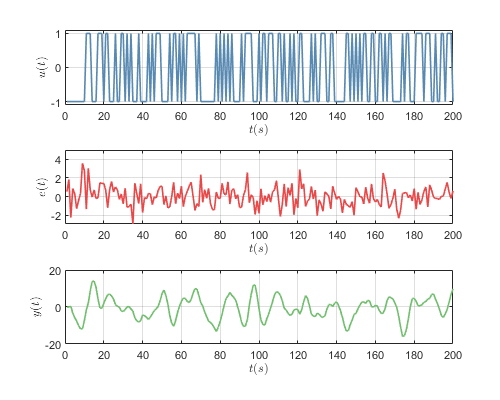

myInput

**Figura 1:** Sinal de entrada $u(t)$, ruído branco $e(t)$ e saída do processo $y(t)$.

Em seguida, as estimativas $\hat\hat{G}_N(e^{j\omega})$ e $\hat{G}_N(e^{j\omega})$ para a janela de Parzen e $\gamma\in\{10,50,100\}$ podem ser observados na Figura 2. Foram consideradas $1000$ amostras, ou seja, $N=1000$.

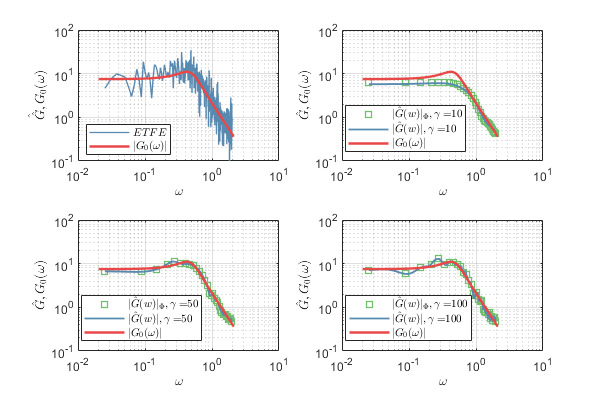

myParzen

**Figura 2:** Estimativas $\hat\hat{G}_N(e^{j\omega})$ e $\hat{G}_N(e^{j\omega})$ para a janela de Parzen e $\gamma\in\{10,50,100\}$

Analisando a ETFE apresentada na Figura 2, é possível observar como essa estimativa é errática em relação à função conhecida $G_0(\omega)$. Por sua vez, examinando as estimativas suavizadas pós-janelamento $\hat{G}_N(e^{j\omega})$, fica clara a melhor precisão em relação à função de transferência simulada quando comparada a ETFE. Por fim, a Figura 2 destaca a equivalência entre $\lim_{N\rightarrow\infty}|U_N(\xi)|^2\approx\Phi_u(\xi)$, visto que $\hat{G}(\omega)$ computado com base em $|U_N(\xi)|^2$ é equivalente a estimativa que emprega a aproximação $\Phi_u(\xi)$. 

Agora, analisando o impacto dos vários valores de $\gamma$, é possível concluir que, com o aumento da largura da janela, há uma maior oscilação do polinômio estimado $\hat{G}(\omega)$. Essa observação pode ser justificada de duas formas:

- Uma janela mais larga, isto é, maiores $\gamma$, pondera (com pesos não nulos) frequências mais distantes de $\omega_0$ na obtenção de $\hat{G}(\omega_0)$. Dessa forma, há uma menor variância da estimativa.

- Entretanto, uma janela mais larga considera estimativas de frequências cada vez mais longes de $\omega_0$. Sendo assim, os valores esperados de $\hat{G}(\omega_0)$ podem oscilar, gerando um alto BIAS. 

Logo, é evidente que devemos procurar o ponto ótimo entre BIAS e variância de $\hat{G}(\omega)$. A otimização dessa relação de compromisso é facilmente visualizada na Figura 2, para qual a melhor estimativa de $\hat{G}(\omega)$ foi encontrada para $\gamma=50$ (valor intermediário). É importante destacar que essa relação depende do número de amostras, uma vez que $N$ influencia a resolução das TDFs.

Em seguida, as estimativas $\hat\hat{G}_N(e^{j\omega})$ e $\hat{G}_N(e^{j\omega})$ para a janela de Bartlett e $\gamma\in\{10,50,100\}$ podem ser observados na Figura 3. 

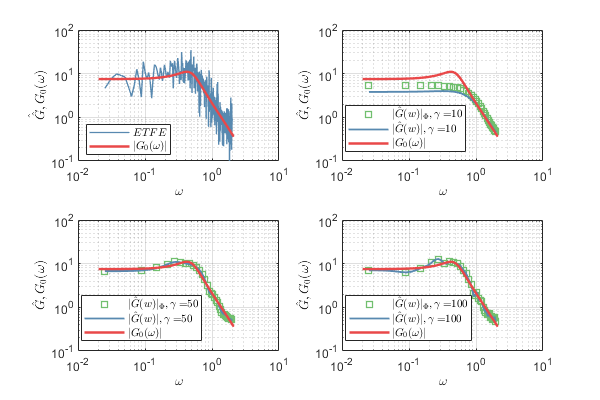

myBartlett

**Figura 3:** Estimativas $\hat\hat{G}_N(e^{j\omega})$ e $\hat{G}_N(e^{j\omega})$ para a janela de Bartlett e $\gamma\in\{10,50,100\}$.

Comparando a Figura 2 com a Figura 3, é evidente a aproximação das estimativas para $\gamma=50$ e $\gamma=100$ para os dois tipos de janela. Todavia, para $\gamma=10$, o janelamento de Bartlett não valida a aproximação$\lim_{N\rightarrow\infty}|U_N(\xi)|^2\approx\Phi_u(\xi)$. Entretanto, esse erro pode ser minimizado aumentando o número de amostras $N$. Para tal, você (usuário), pode alterar o $N$ no código `myInput` e re-executar as células dessa seção.

Por fim, para o janelamento de Hamming, encontra-se as estimativas ilustradas na Figura 4.

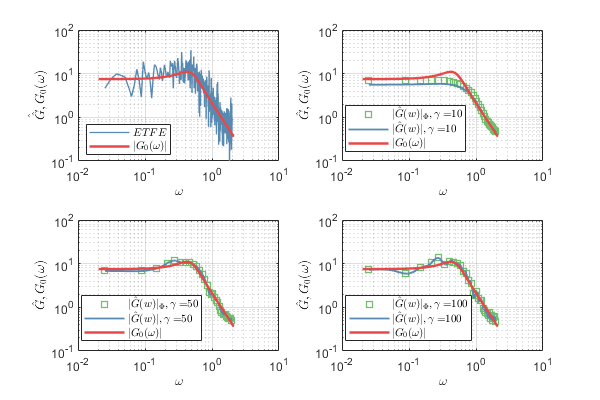

myHamming

**Figura 4:** Estimativas $\hat\hat{G}_N(e^{j\omega})$ e $\hat{G}_N(e^{j\omega})$ para a janela de Hamming e $\gamma\in\{10,50,100\}$.

Assim como para a formulação de Bartlett, para $\gamma=10$, o janelamento de Hamming não valida a aproximação$\lim_{N\rightarrow\infty}|U_N(\xi)|^2\approx\Phi_u(\xi)$. Esse erro pode, novamente, ser minimizado aumentando o número de amostras $N$.

## **Referências bibliográficas**

[1] L. LJUNG. **System Identification: Theory for the User**. Pearson, 1998. 2nd edition, ISBN 9788131744956.